# Intermittency model description and examples

This livescript contains the following information:

- Descriptions of model parameters

- Descriptions of model equations

- Examples of how to run the model and plot results

Additional description and contextualization of the model can be found in: 

- Tilsen, S. *Phrasal rhythmicity and the sources of temporal intermittency in speech* 

- Tilsen, S. (2019) *Syntax with oscillators and energy levels.* Language Science Press.

Please note that this model is a work-in-progress, and a number of future improvements are planned.

## Model parameters

Below are described the parameters used in `intermittency_model.m`. The defaults are defined in the function `model_default_params.m`, but can be replaced by passing them as fields in an input structure (see how to run the model below). The variable names, default values, and short descriptions are provided for each parameter. The effects of their values can be better understood by examining the model equations. Note the following abbreviations:

- C,c : concept system

- S,s : syntactic system

- F : feedback system

- E : excitation potential levels

- A : annealer

- M : excitation monitoring system

addpath('.\helpers');
P = model_default_params;
dp = @(ptype)disp_pars(P,ptype);

Simulation parameters:

dp('simulation');

            name             val                    desc                
    ____________________    _____    ___________________________________

    "T"                         5    "maximal run time"                 
    "stop_on_completion"    0.001    "stop if the sequence is completed"
    "dt"                    0.001    "time step"                        



Systems parameters:

p = dp('systems');

       name                 val                                                        desc                                          
    __________    ________________________    _______________________________________________________________________________________

    "Nc"          {[                 100]}    "number of c-systems"                                                                  
    "Ns"          {[                   3]}    "number of s-systems"                                                                  
    "Sx0"         {[0.5000 0.3000 0.1000]}    "initial syntactic system activation"                                                  
    "S_S"         {3×3 double            }    "s-to-s coupling matrix"                                                               
    "C_S_prop"    {[              0.3333]}    "proportion of systems coupled to verbal S-syst

This is the syntactic system-to-syntactic system coupling matrix for an SVO utterance, where the rows/cols correspond to N+ (S), V, and N- (O) s-systems:

disp(p.val{p.name=='S_S'})

     0     1     0
     1     0    -1
     0    -1     0



For further detail, see Tilsen (2019). *Syntax with oscillators and energy levels*.

Noise amplitudes:

dp('noise amplitude');

      name       val                  desc               
    _________    ___    _________________________________

    "eta_Cp"     0.1    "c-system phase noise"           
    "eta_Cx"     0.1    "c-system activation noise"      
    "eta_Sp"     0.1    "s-system phase noise"           
    "eta_Sx"     0.5    "s-system activation  noise"     
    "eta_Sx0"    0.1    "s-system activation reset noise"



Activation coupling strength parameters. Currently the default model includes only c-to-s activation coupling.

dp('activation coupling strength');

      name      val          desc       
    ________    ___    _________________

    "chi_SC"     0     "s-to-c coupling"
    "chi_SS"     0     "s-to-s coupling"
    "chi_CC"     0     "c-to-c coupling"
    "chi_CS"     4     "c-to-s coupling"



Phase coupling strength parameters:

dp('phase coupling strength');

      name      val           desc       
    ________    ____    _________________

    "psi_SC"      10    "s-to-c coupling"
    "psi_SS"      10    "s-to-s coupling"
    "psi_CC"       0    "c-to-c coupling"
    "psi_CS"    0.05    "c-to-s coupling"



Global excitation potential parameters:

dp('global excitation potential');

      name       val        desc     
    _________    ___    _____________

    "gw_ub"      1.1    "upper limit"
    "gw_lb"        0    "lower limit"
    "gain_gw"    0.1    "gain"       



Syntactic-system excitation potential parameters:

dp('s-system excitation potential');

       name       val                    desc               
    __________    ____    __________________________________

    "sigma_VE"    0.05    "width of force regions"          
    "gain_VE"        1    "strength of excitation potential"



Annealing parameters:

dp('annealer');

      name       val                           desc                        
    _________    ___    ___________________________________________________

    "gain_Ai"    1.2    "gain of annealer in initial organization phase"   
    "gain_Ar"      6    "gain of annealer after initial organization phase"



Excitation monitor parameters:

dp('excitation monitor');

           name           val                          desc                      
    __________________    ____    _______________________________________________

    "Me_unocc_cost"         15    "cost of unoccupied level"                     
    "Me_multiocc_cost"      15    "cost of multiply occupied level"              
    "Me_decay"              10    "decay rate"                                   
    "sigme_VMe"           0.05    "width of excitation monitor potential"        
    "reset_Me"             0.5    "threshold for Monitor-induced reset"          
    "reorg_Me"            -0.5    "threshold for Monitor-induced regorganization"
    "eps_Sx"              0.01    "supression value for syntactic systems"       
    "eps_Cx"              0.01    "degeneracy reset factor for concept systems"  



Feedback parameters:

dp('feedback');

        name                  val                                     desc                      
    ____________    ________________________    ________________________________________________

    "tau_Fx_dem"    {[0.5000 0.5000 0.5000]}    "feedback threshold for syntactic systems"      
    "tau_Sx_sel"    {[                   1]}    "threshold for syntactic system feedback growth"



## Model equations

The model is implemented with a simple numerical method (first-order Euler). At each time step every dynamical variable is updated with an equation of the form:

    
$$x(t)=x(t-1)+\frac{\Delta x}{\Delta t} \cdot \delta t$$


with time indices $t=1,2,...,(T/\delta t)$

For convenience in presenting the equations below, $\dot{x}$ is substituted for $\frac{\Delta x}{\Delta t}$, hence:

    
$$x(t)=x(t-1)+\dot{x}(t)\cdot \delta t$$


The specific update equations in the model are the following:

    $\theta^C_i(t)=\theta^C_i(t-1)+\dot{\theta}^C_i\cdot\delta t$         phase for concept system $i$

    $\theta^S_m(t)=\theta^S_m(t-1)+\dot{\theta}^S_m\cdot\delta t$         phase for syntactic system $m$

    $x^C_i(t)=x^C_i(t-1)+\dot{x}^C_i\cdot\delta t$         activation for concept system $i$

    $x^S_m(t)=x^S_m(t-1)+\dot{x}^S_m\cdot\delta t$         activation for syntactic system $m$

    $x^F_m(t)=x^F_m(t-1)+\dot{x}^F_m\cdot\delta t$         feedback for syntactic system $m$

    $E_l(t)=E_l(t-1)+\dot{E}_l\cdot\delta t$           value of excitation level $l$

    $A(t)=A(t-1)+\dot{A}\cdot\delta t$             annealer state

    $M(t)=M(t-1)+\dot{M}\cdot\delta t$         excitation monitor

For phase variables, $2\pi$-periodicity is imposed by taking the updated value modulo $2\pi$:

    
$$\theta^C_i(t)=\theta^C_i(t)\ (\mathrm{mod}\ 2\pi)$$


    
$$\theta^S_m(t)=\theta^S_m(t)\ (\mathrm{mod}\ 2\pi)$$


Note the following:

- Concept systems are indexed by $i$ and $j$

- Syntactic systems are indexed by $m$ and $n$. For convenience, the indices correspond to the order in which syntactic systems are selected.

- Excitation potential levels are indexed by $l$

- $U$ is a random number from a uniform distribution on the interval (0,1)

- $\eta$ parameters are the noise terms described above. 

Concept system phase:

    
$$\dot{\theta}^C_i = \eta^{C\theta}\cdot U + \omega+\psi_{SC}\cdot\sum_{m}\left(-\sin(\phi^{SC}_{mi})\cdot w^{SC}_{mi}\right) + \psi_{CC}\cdot\sum_{j}\left(-\sin(\phi^{CC}_{ij})\cdot w^{CC}_{ij}\right)$$


where:

    $\omega=2\pi f$ is the intrinsic oscillator frequency in radians per second

    $\phi^{SC}_{mi} = \theta^C_i - \theta^S_m$ is the phase difference between the concept system $i$ and syntactic system $m$

    $w^{SC}_{mi}$ is the syntactic-conceptual system coupling matrix

    $\phi^{CC}_{ij} = \theta^C_i - \theta^C_j$ is the phase difference between the concept system $i$ and concept system $j$

    $w^{CC}_{ij}$ is the conceptual-conceptual system coupling matrix

Syntactic system phase:

    
$$\dot{\theta}^S_m = \eta^{S\theta}\cdot U + \omega+\psi_{SS}\cdot\sum_{n}\left(-\sin(\phi^{SS}_{mn})\cdot w^{SS}_{mn}\right) + \psi_{CS}\cdot\sum_{i}\left(-\sin(\phi^{CS}_{im})\cdot w^{CS}_{im}\right)$$


where:

    $\phi^{SS}_{mn} = \theta^S_n - \theta^S_m$ is the phase difference between the syntactic system $m$ and syntactic system $n$

    $w^{SS}_{mn}$ is the syntactic-syntactic system coupling matrix

    $\phi^{CS}_{im} = \theta^S_m - \theta^C_i$ is the phase difference between the syntactic system $m$ and concept system $i$

    $w^{CS}_{im}$ is the concept-syntactic system coupling matrix

Concept system activation:

    
$$\dot{x}^C_i=-\left(x^C_i-\left(\mathcal{E}_i+\eta^{Cx}\cdot U\right)\right)$$


where:

    $\mathcal{E}_i$ is the driving force from the environment on concept system $i$

Syntactic system activation:

    
$$\dot{x}^S_m=\eta^{Sx}\cdot U+V^{S}_m+W\left(x^S_m\right)+\chi_{CS}\cdot\sum_i w^{CS}_{im}\cdot (F^{Sx}_m)$$


where:

    $V^{E}_m=\alpha_{Ve}\cdot \frac{A}{\delta t} \cdot \sum_l{V(x^S_m,E_{l})}$ is the force on syntactic system $m$ associated with excitation potential forces

    $\alpha_{Ve}$ is the gain of the excitation potential forces

    $A$ is the current state of the annealing system

    ${V(x^S_m,E_{l})} = -(x^S_m-E_l)\cdot e^{-\ {\frac{\left(x^S_m-E_l\right)^2}{2\sigma_{VE}^2}}$is the excitation potential force between level $l$ and syntactic system $m$. 

    $W\left(x^S_m\right)=\alpha_{W}\cdot\left(W^{\text{lower}}(x^S_m)+W^{\text{upper}}(x^S_m)\right)$ is the global activation potential

    $W^{\text{lower}}(x^S_m)=\frac{1}{x^S_m-W_{lower}}$  is the lower bound component of the global activation potential

    $W^{\text{upper}}(x^S_m)=\frac{-1}{W_{upper}-x^S_m}$ is the upper bound component of the global activation potential

    $F^{Sx}_m=\begin{cases}1,\  \text{if}\ F^{x}_m < \tau_{dem}\\ 0,\ \text{if}\ F^x_m\ge\tau_{dem}\end{cases}$  This factor enforces the condition that demoted syntactic systems are no longer coupled to concepts.

Syntactic system feedback:

    
$$\dot{F}^x_m=\begin{cases} 1,\ \text{if}\ x^S_m>\tau_{sel}\\ 0, \ \text{if}\ x^S_m\le\tau_{sel}\end{cases}$$
 

This states that feedback for syntactic system $m$ increases when system $m$ is selected.

Excitation levels:

    $\dot{E}_l=0$   Excitation level values are constant in this version of the model, although note that the number of above-ground levels changes upon reorganization (see below).

Excitation monitoring system:

    
$$\dot{M}=M^{unocc}\cdot \mathcal{E}^{unocc}+M^{multiocc}\cdot \mathcal{E}^{multiocc}+M^{decay}\cdot(-1-M)$$


where:

    $\mathcal{E}^{multiocc}=\sum_{mn, m\neq n}x^S_mx^S_n\cdot V^{M}(x^S_m,x^S_n)$ is the cost associated with multiply-occupied levels, where:

    
$$V^{M}(x^S_m,x^S_m)=e^{\frac{-\left(x^S_m-x^S_n\right)}{2\sigma_{V^{M}}^2}}$$


    $\mathcal{E}^{unocc}=\sum_{l}E_l\cdot \min_m{\sqrt{(E_l-x^S_m)^2}}}$ is the cost associated with unoccupied levels

Annealing system:

    
$$\dot{A}=\begin{cases} \begin{cases} A^{init},\ \text{before any selection, or after degeneracy}\\ A^{reorg},\ \text{otherwise} \end{cases}, A<1 \\ 0,\ A\ge1\end{cases}$$


 This posits that the cooling rate is $A^{init}$ before any systems have been selected and $A^{reorg}$ after systems have been selected, and that the annealer state stops increases when $A\ge1$.

Excitation operations:

After the above updates, excitation operations are applied, based on various conditions described below. Note that the following logical values are calculated each time step:

    $sel_{m}=x^S_m>1$:     indicates whether syntactic system $m$ is currently selected

    $dem_m=sel_m\ \land\ F^x_m\ge\tau_{dem}$:    flag syntactic system $m$ for demotion if it is selected and if feedback for system $m$ is greater than or equal to the demotion threshold

    $sup_m=\lnot sel_m\ \land\ F^x_m\ge\tau_{dem}$:    indices whether syntactic $m$ is currently supressed (i.e., it is not selected but is has feedback state $\ge\tau_{dem}$)

Condition: degeneracy before any selection

    $M(t)>M^{reset}\ \land\ \forall_m \lnot sup_m$ :

        $A\rightarrow0$                    the annealer is reset to $0$

        $M\rightarrow0$                    the excitation monitoring system is reset to 0

        $x^S_m\rightarrow x^S_0 + \eta^{Sx0}\cdot U$     syntactic systems are reset to their initial values with a random perturbation

        $C\rightarrow \epsilon_{Cx}\cdot C$            concept system values are diminished

Condition: degeneracy after any system has been selected and supressed

    $M(t)>M^{reset}\ \land\ \exists_m\ sup_m$ :

        $A\rightarrow0$                    the annealer is reset to $0$

        $M\rightarrow0$                    the excitation monitoring system is reset to 0

        
$$x^S_m\rightarrow \begin{cases} \eta^{Sx0}\cdot U+\frac{m}{N_{unsel}},\ \lnot sup_m\\ 
\epsilon_{Sx},\ \ sup_m\end{cases}$$
     

            The above states that the activations of syntactic systems that have not been supressed are reset to evenly spaced values on the interval $\left[\frac{1}{N_{unsel}},1\right]$, where $N_{unsel}$ is the number of systems that have not yet been selected, with a random perturbation $\eta^{Sx0}\cdot U$. The activations of syntactic systems that have been supressed are set to $\epsilon_{Sx}$. Note that this formulation of the operation requires that syntactic systems be indexed in the order in which they are canonically selected.

        $C\rightarrow \epsilon_{Cx}\cdot C$            concept system values are diminished by the factor $\epsilon_{Cx}$

Condition: initial coherence

    $M(t)<M^{reorg}\ \land\ \forall m\ \lnot sel_m$     : when the monitor reaches a coherence threshold and not any syntactic systems have yet been selected:

        $A\rightarrow0$                    the annealer is reset to $0$

        $M\rightarrow0$                    the excitation monitoring system is reset to 0

        $E\rightarrow r^C(E)$              the canonical reorganization operation is applied to the excitation potential levels. This operation eliminates the lowest non-ground level from the potential, reflecting the hypothesis that the potential itself emerges from the excitation of conceptual-syntactic systems.

        $x^{Sx}_m\rightarrow \epsilon_{Sx}, \text{if}\ dem_m$    the activations of demoted syntactic systems are set to $\epsilon_{Sx}$

Condition: within sequence coherence

       $\exists m\ dem_m$     : when a syntactic system reaches the demotion state 

        $A\rightarrow0$                    the annealer is reset to $0$

        $M\rightarrow0$                    the excitation monitoring system is reset to 0

        $E\rightarrow r^C(E)$              the canonical reorganization operation is applied to the excitation potential levels. This operation eliminates the lowest non-ground level.

        $x^{Sx}_m\rightarrow \epsilon_{Sx}, \text{if}\ dem_m$    the activations of demoted syntactic systems are set to $\epsilon_{Sx}$

## Examples

#### How to run the model and plot the results

sim = intermittency_model;

All of the dynamical variables and parameters are in the output structure (here named `sim`)`:`

sim

sim = struct with fields:
                    An: [5000×1 double]
                   C_C: [100×100 double]
                   C_S: [3×100 logical]
              C_S_prop: 0.3333
                    Cp: [5000×100 double]
                    Cx: [5000×100 double]
                 Cx_eq: [0.0402 0.0261 0.0222 0.0051 0.0040 0.0780 0.0630 1.0588 0.0166 0.0407 0.0527 0.0746 0.0963 0.0866 0.0368 0.0990 0.0018 0.0078 0.0260 0.0472 0.0718 0.0916 0.0059 0.0040 3.5407e-04 0.0080 0.0473 0.0992 0.0625 0.0635 0.0198 … ]
                    EV: {6×2 cell}
                    Ex: [5000×5 double]
                    Fx: [5000×3 double]
                    Me: [5000×1 double]
              Me_decay: 10
      Me_multiocc_cost: 15
         Me_unocc_cost: 15
                 N_ixs: [1 2 3 4 6 7 8 9 10 11 12 13 14 15 16 17 18 20 21 22 24 25 26 27 28 30 31 32 33 34 35 36 39 40 41 42 43 44 45 46 49 50 51 52 53 54 55 57 58 59 60 61 62 63 64 66 67 68 69 70 71 73 74 75 76 77 81 82 83 84 85 86 87 88 89 90 92 93 …

Passing the output structure to the function `plot_sim` will plot some of the variables. Other variables can be plotted by accessing the output structure above.

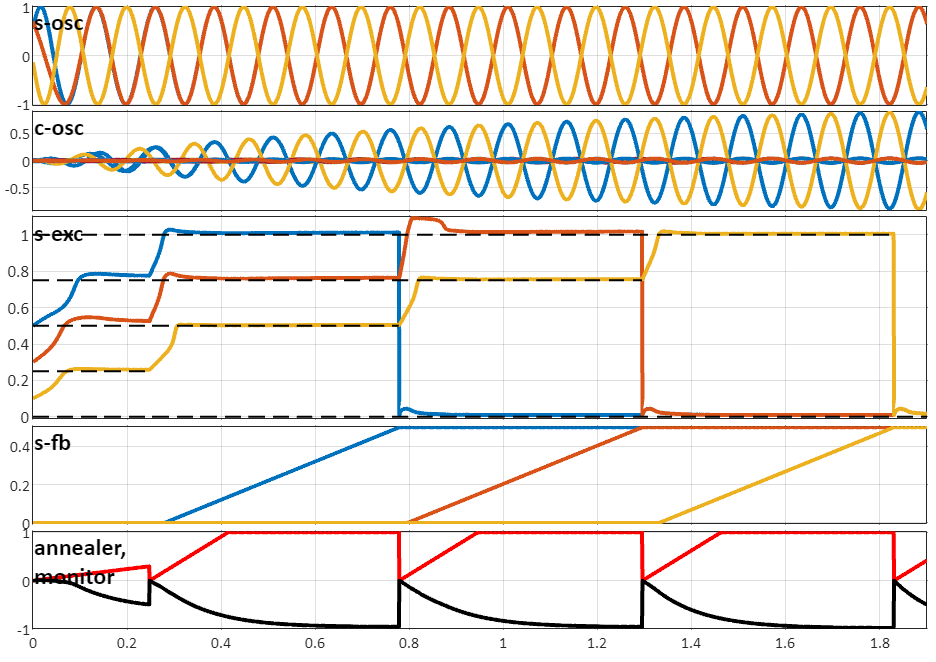

plot_sim(sim)

#### Changing parameters

Recall that the default parameters are specified in:

P = model_default_params;
head(P)

             name                       val                    type                                 desc                        
    ______________________    ________________________    ______________    ____________________________________________________

    {'T'                 }    {[                   5]}    {'simulation'}    {'maximal run time'                                }
    {'stop_on_completion'}    {[          1.0000e-03]}    {'simulation'}    {'stop if the sequence is completed'               }
    {'dt'                }    {[          1.0000e-03]}    {'simulation'}    {'time step'                                       }
    {'Nc'                }    {[                 100]}    {'systems'   }    {'number of c-systems'                             }
    {'Ns'                }    {[                   3]}    {'systems'   }    {'number of s

All of the parameters can be overwritten by providing them as fields of a single input structure. For example, if we wanted to (i) prevent the simulation from stopping upon completion of the sequence, (ii) decrease the maximal run time to 3 s, and (iii) increase the noise amplitude for syntactic system activation, we would do the following:

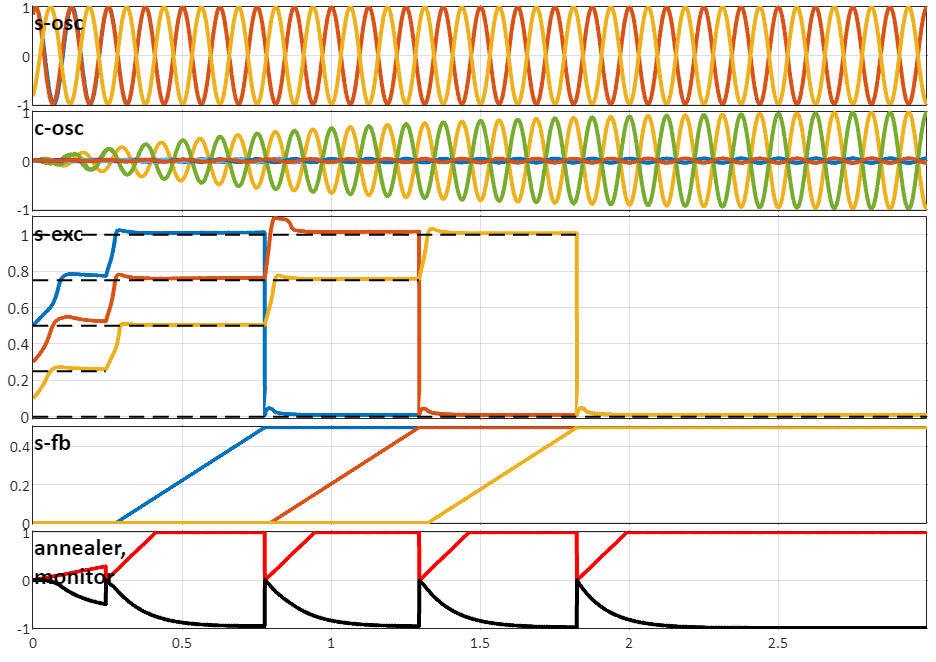

par.stop_on_completion = false;     %(i)
par.T = 3;                                              %(ii)
par.eta_Sx = 1;                                    %(iii)

sim = intermittency_model(par);
plot_sim(sim)

Helper functions for this livescript:

function [P] = disp_pars(P,ptype)
P = P(ismember(P.type,ptype),{'name' 'val' 'desc'});
P.name = string(P.name);
P.desc = string(P.desc);
try
    P.val=cell2mat(P.val);
catch
end
disp(P);
end